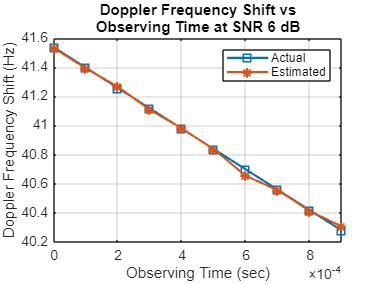

fc = 2.4e9;             % Carrier Frequency
c = 3e8;                % Speed of Light
lambda = c/fc;          % Wavelength

vd_act = (lambda/(sind(10)))*fd_act;
vd_hat = (lambda/(sind(10)))*fd_hat_SNR_8_avg;

t = 0:1e-4:9*1e-4;
figure;
plot(t,fd_act,"-square","MarkerIndices",1:10,"LineWidth",1.5,"MarkerSize",7);
hold on;
plot(t,fd_hat_SNR_6_avg,"-*","MarkerIndices",1:10,"LineWidth",1.5,"MarkerSize",7);
hold off;
grid on;
xlim([0,t(end)]);
line1 = "Doppler Frequency Shift vs";
line2 = "Observing Time at SNR 6 dB";
title([line1,line2]);
xlabel("Observing Time (sec)");
ylabel("Doppler Frequency Shift (Hz)");
legend("Actual","Estimated")

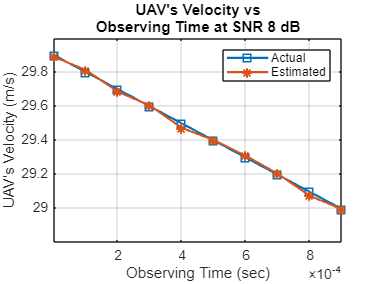


figure;
plot(t,vd_act,"-square","MarkerIndices",1:10,"LineWidth",1.5,"MarkerSize",7);
hold on;
plot(t,vd_hat,"-*","MarkerIndices",1:10,"LineWidth",1.5,"MarkerSize",7);
hold off;
grid on;
xlim([0,t(end)]);
line1 = "UAV's Velocity vs";
line2 = "Observing Time at SNR 8 dB";
title([line1,line2]);
xlabel("Observing Time (sec)");
ylabel("UAV's Velocity (m/s)");
legend("Actual","Estimated")

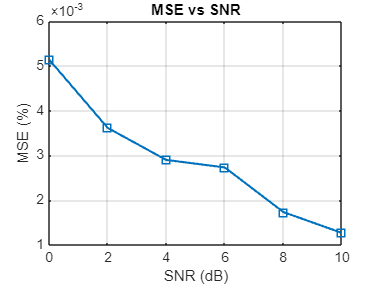

mse_0_db = mean((fd_act-fd_hat_SNR_0_avg).^2)*10;
mse_2_db = mean((fd_act-fd_hat_SNR_2_avg).^2)*10;
mse_4_db = mean((fd_act-fd_hat_SNR_4_avg).^2)*10;
mse_6_db = mean((fd_act-fd_hat_SNR_6_avg).^2)*10;
mse_8_db = mean((fd_act-fd_hat_SNR_8_avg).^2)*10;
mse_10_db = mean((fd_act-fd_hat_SNR_10_avg).^2)*10;

mse = [mse_0_db,mse_2_db,mse_4_db,mse_6_db,mse_8_db,mse_10_db];
SNR = 0:2:10;
figure;
plot(SNR,mse_s,"-square","MarkerIndices",1:6,"LineWidth",1.5,"MarkerSize",7);
grid on;
xlim([0,SNR(end)]);
title("MSE vs SNR");
xlabel("SNR (dB)");
ylabel("MSE (%)");